## **RaspberryPi with MATLAB Workshop**

**Required Software:**

- MATLAB 2023a (older versions may work too, but are not tested )

- MATLAB Support Package for RaspberryPi Hardware (Install the package under the Home tab --> Add-Ons)

**Required Hardware:**

- Raspberry Pi with a connected PCB

- 3D printed Robot Arm

- Battery pack set to ON

- Ethernet cable (+ optional Ethernet to USB Adapter)

- Micro-USB cable

### Setup

1. Check that you have all required Hardware and Software

2. Connect the Raspberry Pi with an Ethernet Cable to your Laptop (use adapter if you don't have an ethernet connector)

3. Connect the Raspberry Pi's Powerport with the USB cable to your Laptop

4.  Wait 1-2 minutes for the raspberry pi to boot

5. In the IP list below, uncomment the IP corresponding to the label on the Raspberry Pi 

6. Run the section below and wait for the connection to establish

clear; close all; clc;
% Try to connnect to raspi with IP
% If you have any problems with this step, please ask for help

% Set the IP of the raspi
% ip = '169.254.215.7'; % 11
ip = '169.254.162.237'; % 04
% ip = '169.254.146.104'; % 06
% ip = '169.254.212.152'; % 15
% ip = '169.254.82.77'; % 10
% ip = '169.254.212.196'; % 07
% ip = '169.254.232.81'; % 03
% ip = '169.254.199.208'; % 12

raspberry_pi = raspi(ip,'pi','raspberry'); 

7. Run the section below to configure the servos on Pin 22 and Pin 23

front_servo = servo(raspberry_pi,23);
back_servo = servo(raspberry_pi,22);
front_servo.MaxPulseDuration = 0.00250;
front_servo.MinPulseDuration = 0.0005;
back_servo.MaxPulseDuration = 0.00250;
back_servo.MinPulseDuration = 0.0005;   

8. Run the section below to command the angles of the front and back joint

% The maximum range for the back servor [0°, 180°]
% and for the front servo is [-90° , 90°] 

angle_back = 45; %deg
angle_front = 45; %deg

% This folder contains the Files you are supposed to work with.
addpath("Functions");

%Command the joint angles to the raspi
commandPosition(back_servo,front_servo, angle_back,angle_front);

%And simultaniously plot the robot
clf
plotRobot(angle_back, angle_front);

### Forward Kinematics

In robotics, we usually care most about the position of the tip of the robot. This tip is called the endeffector. Forward Kinematics describes the common problem of localizing the endeffector in the coordinate frame using the given angles q1 (angle_back) and q2 (angle_front).

**TODO:** Modify the forwardKinematics function to calculate the position of endeffektor E of the robot. We choose the following Coordinate System:

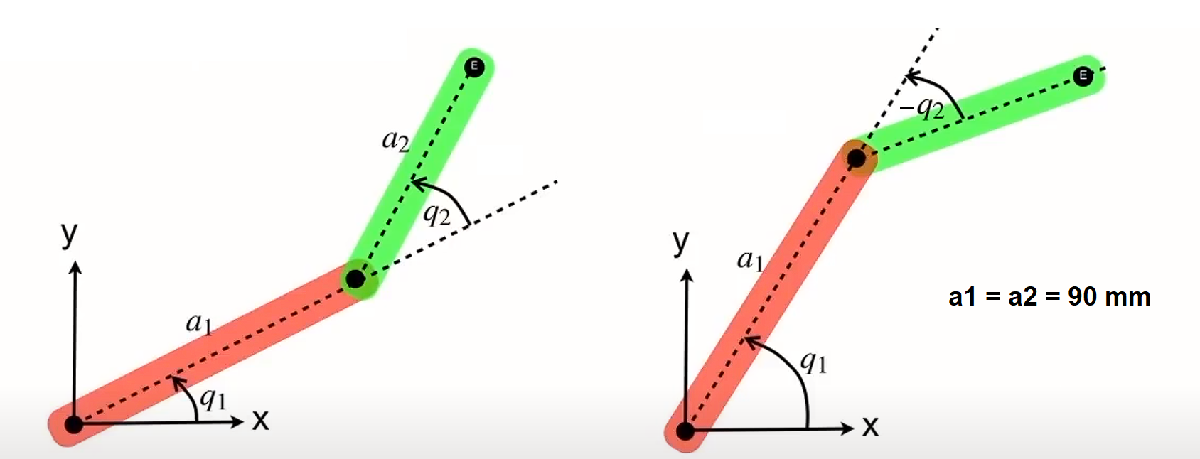

%Desired angles of the robot
angle_back = 45; %deg
angle_front = 45; %deg

% Modify the forwardKinematics.m file to calculate the endeffector position
% x_EE and y_EE
[x_EE, y_EE] = forwardKinematics(angle_back,angle_front);

%Add the position of the endeffektor in the plot as a subtitle
clf
plotRobot(angle_back, angle_front);
subtitle(sprintf("xEE = %.2f mm, yEE = %.2f mm", x_EE, y_EE));

### **Workspace**

Both servos can only rotate by 180°: 

- angle_back : 0° - 180°

- angle_front: -90° - 90 °

The robot arm is therefor not able to reach all possible points within its maximum radius. The set of all points a robot can reach is called the workspace. The workspace is the space in which the endeffector can be placed with the right combination of the joint angles.

**TODO: **Modify the getWorkspace function to calculate the workspace. The getWorkspace() function should return the boundary of the workspace.

%Desired angles of the robot
angle_back = 45; %deg
angle_front = 45; %deg

%Plot the robot
clf
plotRobot(angle_back, angle_front);

hold on

%Get the boundary points enclosing the workspace.
%Hint: You can approximate the workspace by sampling points within the workspace
%and calculating the boundary around these sample points.
[x_boundary, y_boundary] = getWorkspace();

% Plot the workspace in the same plot
plot(x_boundary, y_boundary, 'c-');

hold off

Great now we have all possible points the robot can reach in this configuration! We are ready to move to the classic challenge of robotics: Inverse Kinematics.

### Inverse Kinematics

Lets say our robot is in this starting position. The classic task in robotics is to now move the endeffector from it's current position to a desired position (red) within the workspace. Let's visualize this problem: 

angle_back = 100;
angle_front = 7;

% We can visualize the robot like this
clf
plotRobot(angle_back, angle_front);
hold on
plot(x_boundary, y_boundary, 'c-');
commandPosition(back_servo,front_servo,angle_back, angle_front);

%Desired endeffektor position
x_des = -50; %mm
y_des = 140; %mm

%Lets visualize the desired position
h_marker = plot(x_des, y_des, '-o', 'MarkerSize', 8, 'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'red', 'Tag', 'myMarker');
hold off

Our task is now to adjust the joint angles to have our endeffector (green) move towards the desired position. You can imagine that this task is not trivial and you would have a hard time trying to adjust the joint angles by hand. Try it yourself by changing the sliders at the top of the section.

**TODO:** After you are done, reset the robot to the default position so we can start on working on a better solution to this problem.

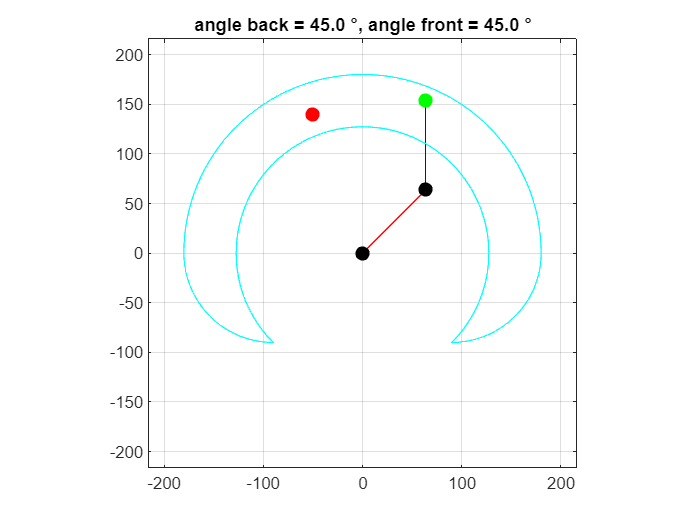

angle_back = 45;
angle_front = 45;

% We can visualize the robot like this
clf
plotRobot(angle_back, angle_front);
hold on
plot(x_boundary, y_boundary, 'c-');
commandPosition(back_servo,front_servo,angle_back, angle_front);

%Desired endeffektor position
x_des = -50; %mm
y_des = 140; %mm

%Lets visualize the desired position
h_marker = plot(x_des, y_des, '-o', 'MarkerSize', 8, 'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'red', 'Tag', 'myMarker');
hold off

Let's now derive an algorithm that will move the robots endeffector in the direction of the desired position so we don't have to do this by hand anymore.

1. As a starting point we revisit the forward kinematics equation


$$x_{EE} = l_1 \cos(q_1) + l_2 \cos(q_1 + q_2) \ \ \ \ \ \ l_1 = length\ of\ back\ segment\\
y_{EE} = l_1 \sin(q_1) + l_2 \sin(q_1 + q_2)\ \ \ \ \ \ \ l_2 = length\ of\ front\ segment


$$


2. We can vectorize this in the following form:

 

3. Differentiation with respect to time yields:

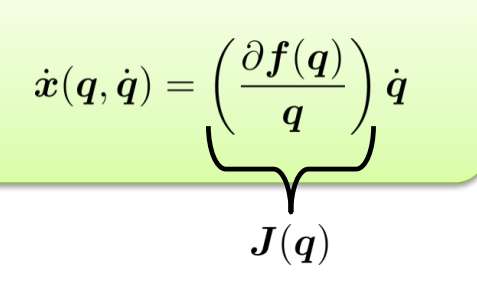         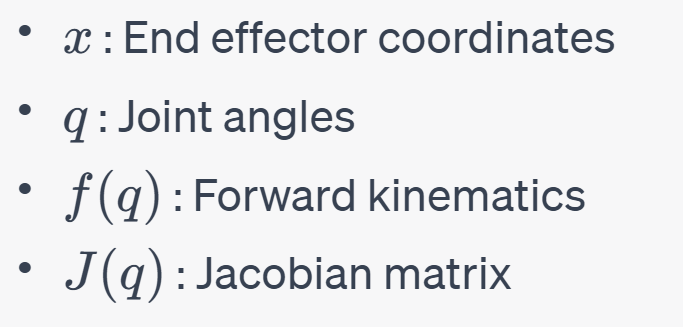

4. Solving after $\dot{q}$ yields:

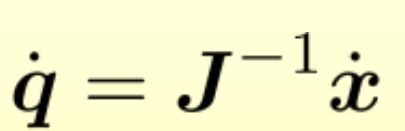

We now have an expression (inverse kinematics) for how we should change the joint angles for a desired change in the end effector position.

**TODO:** Let's implement this:

% The jacobi matrix (here 2x2) can be calculated for any given joint configuration:
% TODO: Modify the getJacobi.m file to calculate the Jacobi Matrix J
J = getJacobi(angle_back,angle_front);

Unrecognized function or variable 'angle_back'.


%Calculate x_dot
x_dot = [x_des - x_EE; y_des - y_EE];

%Inverse kinematics (use pseudo inverse for numeric stability)
q_dot = pinv(J) * x_dot;

%Increment the angle by a small step in q_dot
angle_back = angle_back + q_dot(1);
angle_front = angle_front + q_dot(2);

%Update the robot
clf
plotRobot(angle_back, angle_front);
commandPosition(back_servo,front_servo,angle_back, angle_front);
hold on
plot(x_boundary, y_boundary, 'c-');
h_marker = plot(x_des, y_des, '-o', 'MarkerSize', 8, ...
        'MarkerEdgeColor', 'red', ...
        'MarkerFaceColor', 'red', ...
        'Tag', 'myMarker');
hold off
% Iteratively perform the inverse kinematic step
                                 

% Hint: Reset the robot by running the section above the current section.

**Bonus Task: **Modify the section above to make the approach faster!

Thank you very much for you participation in the workshop!

Feel free to play around with the code as much as you like and ask any questions you may have.

Best,

~ The Student Ambassadors of MathWorks at TUM 

Paola and Samuel

Sources:

Formulas in the Inverse Kinematic section have been derived with help of the TUM Course "Regelung moderner Leichtbauroboter WS 22/23"

from Alexander Dietrich.